# Neurotech 2021 - Homework 1 

## Descriptive stats, probability, and distributions

**Sam Michalka - Olin College of Engineering**

## Commentary on this assignment

This notebook presumes basic Matlab knowledge including using data tables, indexing with logical vectors, calling functions, and plotting. If you are new to Matlab or feeling rusty, you may want start by working through the [MATLAB onramp](https://matlabacademy.mathworks.com/R2020b/portal.html?course=gettingstarted&s_tid=course_mlor_start1) (about 2 hours of content available; you'll need to sign in with your Mathworks account... you should already have one through Olin or you can create one for free; long link: https://matlabacademy.mathworks.com/R2020b/portal.html?course=gettingstarted&s_tid=course_mlor_start1). Regardless of your level of Matlab background, you'll want to take advantage of the extensive documentation. For any function, you can just type help functionname to see more. Or doc functionname if you want it to open in a separate window. Or use your favorite search engine monopoly.

You may also want to check out this page about how to access info in tables in Matlab: [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) I suggest the section called **Extract Data Using Dot Notation and Logical Values.**

help sqrt

## Skills and topics

- Load and manipulate real data in using software tools

- Compute and understand summary statistics (mean, median, mode, standard deviation, variance, interquartile range) for data. 

- Create meaningful visualizations of distributions of data (e.g., histograms).

- Compute true positive, false positive, true negative, and false negative counts and rates.

- Calculate probabilities from data.

## The situation

You and your team have developed a new screening for Parkinson’s disease. Hooray, you’re amazing! The attached data ([Parkinsons2021.mat](https://drive.google.com/file/d/1YsgbEEB8HhqZwhuBItDqC4-GZturOI6N/view?usp=sharing) also on Canvas) are from a study to evaluate your screening. Since you are trying to evaluate the effectiveness of your screening, you recruit a group of people with known Parkinson’s disease diagnoses (let’s assume that these “known” diagnoses are accurate and attainable). While the actual prevalence of Parkinson’s disease in the world is much lower, in your selected group, 50% of participants have Parkinson’s disease and 50% do not.

Prevalence of Parkinson’s disease in the US population: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6039505/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6039505/)

Paper on postural stability tests: [https://www.rehab.research.va.gov/jour/04/41/5/pdf/Chaudhry.pdf](https://www.rehab.research.va.gov/jour/04/41/5/pdf/Chaudhry.pdf)

The first step is to load the data and take a look. I strongly suggest that you load the data as a table.

load('Parkinsons2021.mat'); %semicolon at the end keeps this from spitting out all the data
size(data) %This tells you the size of your data table 

ans =    526     7


head(data) % This shows the first 8ish entries instead of spitting out all the data 

ans = 8×7 table
    reality    diagnosis    age    temperature        state         PSI         reach    
    _______    _________    ___    ___________    _____________    _____    _____________

       1           1        56        36.3        Florida          70.74    [1x10 double]
       0           0        70        36.6        Florida          58.57    [1x10 double]
       0           1        54        36.9        California       61.48    [1x10 double]
       1           1        52        37.1        California       78.37    [1x10 double]
       1           1        63        37.2        California       76.15    [1x10 double]
       0           0        70        36.5        Massachusetts    64.13    [1x10 double]
       0           0     

The data table has 7 variables:

- reality: this is the true disease status of each person. 1 means they have Parkinson's disease, and 0 means they do not.

- diagnosis: this is the diagnosis by your new screening test. 1 means the test is positive for Parkinson's disease, 0 means the test is negative

- age: this is the age in years of each participant. All participants should be age 45 or older.

- temperature: this is the person's temperature at the time of the screening in degrees Celsius

- state: this is the name of the state in the US where the testing was conducted

- PSI: this is the postural stability score for each person (see article above for more info)

- reach: these are the scores for 10 trials of a reaching task, the more consistent the scores, the better.

size(data.reach)

ans =    526    10


## Describing data with graphs and statistics

Let's start with one variable (data.temperature). From the description above, we know that this refers to a person's body temperature in degrees Celsius. First, we'll plot the data using a histogram to get a sense of it.

nBins = 8; 
histogram(data.temperature,nBins); 
title('Histogram of Temperature (C)');
xlabel('Temperature (C)'); ylabel('Count');

You can change the number of bins to provide different levels of resolution (try a few values). Now, we're going to describe what type of data this is and choose a single "statistic" to describe it. A "statistic" refers to a characteristic of a sample (some data).

For info on data types in statistics, check out: [https://towardsdatascience.com/data-types-in-statistics-347e152e8bee,](https://towardsdatascience.com/data-types-in-statistics-347e152e8bee,) or look up data types in statistics.

For info on descriptive statistics, check out: [https://ncss-wpengine.netdna-ssl.com/wp-content/themes/ncss/pdf/Procedures/NCSS/Descriptive_Statistics-Summary_Tables.pdf](https://ncss-wpengine.netdna-ssl.com/wp-content/themes/ncss/pdf/Procedures/NCSS/Descriptive_Statistics-Summary_Tables.pdf) or look up descriptive statistics.

Type of data: continuous, ratio

Descriptive summary statistic: mean 

mean(data.temperature)

Explain your choice of summary statistic: I chose to summarize with the mean, because the data are continuous and the distribution looks symmetrical with no major outliers.

#### Exercise 1: Repeat this process for each of the variables in the data table. 

There may be multiple reasonable choices so explain your reasoning under "why". 

*Note: Since data.reach has multiple entries for each person, you may first want to determine an appropriate summary statistic to describe the 10 entries per person, make that a new variable, then proceed. You can create a new table variable by assigning values to data.newvariablename. If you run into errors, you may be having a problem due to dimensions not matching (check out the 'dim' input for whatever function you're calling in Matlab). *

Graph:

Type of data: 

Descriptive summary statistic:  

## Probability of discrete random variables

In a bit, we will think about the effectiveness of our Parkinson's disease screening. First, we want to build a little foundation about probability. 

The following resources may be helpful. You do not need to work through these all thoroughly, so use these and other resources as they work for you. You can optionally dig in deeper if you're excited about the mathematical foundation, or skip over that part if it's not helpful. You can ask questions by commenting on the pdfs. 

- [Counting Sets (MIT 18.05 - Reading 1b) ](https://drive.google.com/file/d/19BA7xEIqM3qPCTQcz2N_5p6_PKFXJSER/view?usp=sharing)

- [Probability: Terminology and Examples (MIT 18.05 - Reading 2) ](https://drive.google.com/file/d/1ptMa_JRKK7slJtR8hnvptrPAJQ-AlaYP/view?usp=sharing)

- If you find it helpful, you can also check your understanding (and find the original online versions of these documents) by checking out the Interactive Reading Questions [here (Links to an external site.)](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/).

- [Interactive Reading Questions for 1b (Links to an external site.)](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/reading-questions-1b/)

- [Interactive Reading Questions for 2 (Links to an external site.)](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/reading-questions-2/)

#### Exercise 2: Explain intersection, union, and complement in your own words (using an example might be helpful).

Now, we'll apply some of these probability concepts to our data. A few tips for counting things in Matlab:

sum(data.diagnosis==1) % This is the count of all of the times where the test diagnosed as positive
height(data) %This is the number of rows of data in the table called data
sum(data.diagnosis~=1) % This is the count of all the times where the test diagnosis was not positive. 
sum(data.diagnosis==0) % This is the count of all the times where the test diagnosis was not positive. (same as above because the options are only 0 or 1)
sum(data.diagnosis==1 & data.state=='California') % Count of all the times where the test diagnosed as positive AND the person was from California
sum(data.diagnosis==1 | data.state=='California') % Count of all the times where the test diagnosed as positive OR the person was from California

#### Exercise 3: If you randomly select someone from your group, what is the probability that they are from Massachusetts?

#### Exercise 4: If you randomly selected someone from your study group, what is the probability that your test will flag them as having Parkinson’s? 

#### Exercise 5: Calculate the accuracy of your screening test: If you randomly select someone from your study group, what is the probability that your test will diagnose them correctly?

Note: it may be helpful to create a new variable called data.correcttest.

## Conditional probabilities

A conditional probability is the probability of something (A) under the condition that something else happened (B). This is denoted as P(A|B), which reads "the probability of A given B". 

Note: In Matlab code, the | symbol means "or". When we write a conditional probablity the | symbol means "given". 

To wrap your head around conditional probabilities, check out:

- [This interactive](https://setosa.io/conditional/) (note that !B means "not B")

- [Section 2 of this reading](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading3.pdf). (We'll revisit the rest of it another time)

#### Exercise 6: If you randomly select someone from your study group who you know does not have Parkinson’s, what is the probability that your test will incorrectly diagnose them with the disease? 

Write this as a conditional probability (with words or symbols) and then calculate using Matlab.

In a whole bunch of situations, we have two binary pieces of information: one representing the "truth" and the other representing a prediction or decision. These are often represented in a table. Be sure to pay attention to which way the table is organized (below, the true condition is across the top, but this is not always the case).

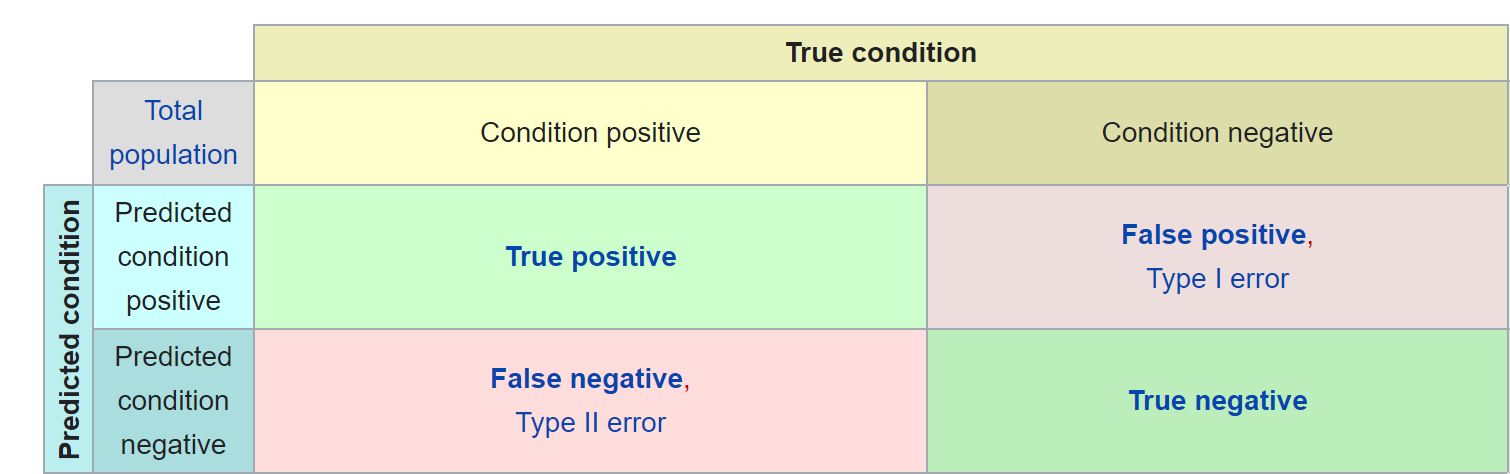 Source: [https://en.wikipedia.org/wiki/Sensitivity_and_specificity](https://en.wikipedia.org/wiki/Sensitivity_and_specificity) 

To make life complicated, there are various terms for the conditional probabilities describing the same situations. When thinking about disease screening, we often use terminology like "false positive" and "false positive rate". When talking about signal detection theory, you'll see terms like "hit" and "miss". In hypothesis testing, we'll see terms like "Type I error" and "Type II error". There are a lot of terms, so let's focus on the true/false positive/negative framing for now. The resources below may be helpful.

- [Wikipedia article on sensitivity and specificity](https://en.wikipedia.org/wiki/Sensitivity_and_specificity)

- [Video on false positives and negatives](https://www.youtube.com/watch?v=kuA72qb6w6c) (note the flipped axes compared to the table above)

#### Exercise 7: Determine the counts of the true positive, true negative, false positive, and false negatives for your screening test. Use these values to calcuate the true positive rate, false positive rate, and true negative rate.

#### Exercise 8: Look up the terms sensitivity and specificity. Which terms above do they equate to? Explain sensitivity and specificity in terms of conditional probabilities.

## Exploring distributions

In this part, we’re going to look at the binomial distribution and start to explore the probability mass function (PMF) and the cumulative distribution function (CDF). 

If you're enjoying the mathy reading, you might want to check this out this r[eading about PMF and CDF](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading4a.pdf) (you probably only need to read section 2.4 to 3.4). 

Or you may want to start with the short explanation below and play around with the visualization tool (also below).

The probability mass function (PMF) is a function over the sample space of a discrete random variable X, which gives the probability that X is equal to a certain value. In equation form:


$$f\left(a\right)=p\left(a\right)\;=\;P\left\lbrack X=a\right\rbrack$$


Big X is a discrete random variable on a sample space, S. Little "a" is a number you can plug in. Sometimes f(a) is often denoted as p(a), since p is a more intuitive letter for the *probability* mass function. I'm using f(a) here in hopes to avoid a little confusion regarding the parameter, *p, *which we will see in a minute.

For example, we toss a fair coin 1 time and want to know the probability of getting some number, *a,* of heads.


$$\begin{array}{l}
f\left(0\right)=0\ldotp 5\\
f\left(1\right)=0\ldotp 5\\
\mathrm{otherwise}\;f\left(a\right)=0
\end{array}$$


Now, let's say we tossed the coin twice (trials =2), with each toss having a probability of 0.5 of being heads.

#### Exercise 9: Fill in the appropriate outputs of our PMF for each number of heads.

It may be helpful to write out all of the possible outcomes (there should be 4).


$$\begin{array}{l}
f\left(0\right)=\\
f\left(1\right)=\;\\
f\left(2\right)=\;\\
f\left(3\right)=\;
\end{array}$$


### Binomial Distribution - PMF

Now, we'll explore the the same type of question as above using a distribution called a binomial distribution. The binomial distribution has 2 parameters: 

- the probability of a success on any given indepenent trial (in our case, flipping a fair coin and getting heads) 

- the  number of trials 

Let's use a Matlab's graphical user interface (GUI or goo-ee) to investigate. Running the line of code below that says disttool should make an interactive window pop up (it will probably also make a picture of what that window looks like pop up in this notebook... but that one is not interactive).

disttool;

Set the distribution type to [binomial](https://en.wikipedia.org/wiki/Binomial_distribution); set the function type to PDF (ours is technically a PMF, since it is discrete, but they are conceptually the same).

Set the Trials to 1; and leave the probability (“Prob”) as 0.5. You may need to adjust the “Upper Bound” that is directly above "Trials", which set the x-axis for the plot. 

If you click on either of the blue +’s, you will see the density value displayed on the left. The density refers to the probability of getting exactly that many positive outcomes (e.g, heads) in a given number of trials (1 in our case). 

Play around with the value of "Prob" to build an intuition for how this works. Make sure you understand why all the values greater than 1 are equal to zero. 

Then change the number of trials to 2 and check that this matches your answer from the last exercise in the previous section. 

*Fun fact: The Bernoulli distribution is a special case of the binomial distribution, where *`N = 1`*.*

#### **Exercise 10: **Set the “Prob” back to 0.5. Increase the number of trials a few times (go up to at least 50).  Describe what happens to the plot and how this translates to the coin flip analogy.

#### **Exercise 11: **Using the PMF (labeled PDF), what is the probability of getting exactly 19 heads in 37 flips of a fair coin?  If you want, confirm this using math. 

### Binomial Distribution - CDF

Any probability mass function (PMF) or probability density function (PDF) has a best friend called the cumulative distribution function (CDF). 

The cumulative distribution function of a random variable X is the function F given by F(a) = P(X ≤ a). Another way of thinking about this is that the cdf outputs the area under the PDF for values up to and including the input value.

In the GUI, set the number of trials to 2 and the Prob to 0.5. 

#### Exercise 12: Use the CDF to determine the probability of getting at least 1 tails on a fair coin.

If you're struggling to visualize the relationship bewtween the PMF and the CDF, this interactive might be helpful: [https://seeing-theory.brown.edu/probability-distributions/index.html#section2](https://seeing-theory.brown.edu/probability-distributions/index.html#section2)

#### Exercise 13: What is the probability of getting 19 or more heads in 37 flips on a coin that has a 0.6 probability of coming up heads?

### Normal Distribution

Now, let’s explore the “normal distribution” using the disttool interface. Notice that the plots become smooth instead of chunky (#peanutbutter), because we're now dealing with continuous data (such as the temperature data in our study). The variable mu (μ) refers to the mean, and sigma ($\sigma$) refers to the standard deviation. 

In the disttool, change the distribution to Normal. 

#### **Exercise 14: **Describe what happens in the PDF plot when you change the mean and what happens when you change the standard deviation. 

#### **Exercise 15: **Switch to the CDF plot.  Describe what happens when you change the mean and what happens when you change the standard deviation of your distribution. 

#### **Exercise 16: **Consider a standard normal distribution (mu = 0, sigma = 1). What is the probability of randomly selecting a value of 1.96 or less?

#### Exercise 17: Create a distribution based on the temperature data. Use this to estimate the probability of a randomly selected person having a temperature below 36 C. How else might you calculate this?